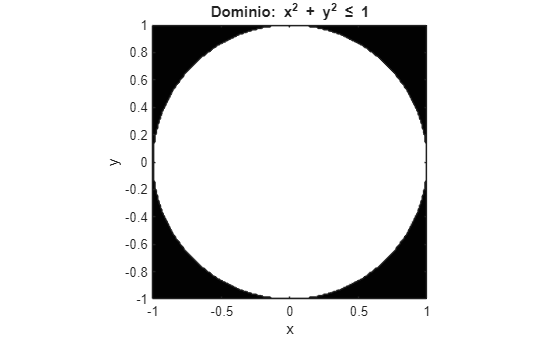

% Laboratorio 2 Calculo Multivariado
% Juan Camilo Garcia Zapata 30000125541

% Modelo 3D de un sólido tipo superficie (Ingeniería Multimedia)

clc; clear; close all;


%  1. DOMINIO


x = linspace(-1,1,200);
y = linspace(-1,1,200);

[X,Y] = meshgrid(x,y);

% Dominio circular: x^2 + y^2 <= 1
D = (X.^2 + Y.^2 <= 1);


%  2. FUNCION


Z = (2 - X.^2 - Y.^2) + 0.3*X;

% IMPORTANTE: evitar NaN para exportación STL
Z(~D) = 0;


%  3. GRAFICA DEL DOMINIO


figure
contourf(X,Y,D,1)
colormap(gray)
title('Dominio: x^2 + y^2 ≤ 1')
xlabel('x')
ylabel('y')
axis equal

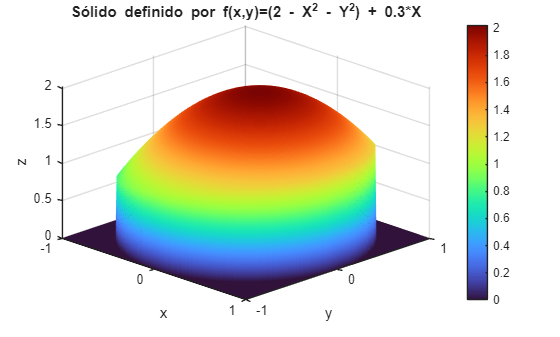



%  4. GRAFICA DEL SOLIDO


figure
surf(X,Y,Z)

title('Sólido definido por f(x,y)=(2 - X^2 - Y^2) + 0.3*X')
xlabel('x')
ylabel('y')
zlabel('z')

colormap turbo
shading interp
colorbar
view(45,30)
axis tight



%  5. DEFINICION SIMBOLICA


syms x y

f = (2 - x^2 - y^2) + 0.3*x;

%  6. INTEGRAL DOBLE


inner = int(f, y, -sqrt(1 - x^2), sqrt(1 - x^2));
V_sym = int(inner, x, -1, 1);

disp('INTEGRAL DOBLE PLANTEADA:')

INTEGRAL DOBLE PLANTEADA:


disp('V = ∫_{-1}^{1} ∫_{-√(1-x^2)}^{√(1-x^2)} (2 - x^2 - y^2 + 0.3x) dy dx')

V = ∫_{-1}^{1} ∫_{-√(1-x^2)}^{√(1-x^2)} (2 - x^2 - y^2 + 0.3x) dy dx



pretty(V_sym)

3 pi
----
  2





%  7. VOLUMEN NUMERICO


V = double(V_sym);

fprintf('\n====================================\n');

fprintf('Volumen del solido = %.6f\n', V);

Volumen del solido = 4.712389


fprintf('====================================\n');



%  8. MODELO 3D PARA IMPRESION (STL)


% Convertir superficie a malla triangular
F = surf2patch(X, Y, Z, 'triangles');

% Convertir a triangulación (OBLIGATORIO en versiones nuevas)
TR = triangulation(F.faces, F.vertices);

% Exportar STL correctamente
stlwrite(TR, 'modelo_multimedia.stl');

disp('Archivo STL generado correctamente: modelo_multimedia.stl');

Archivo STL generado correctamente: modelo_multimedia.stl
